Question 1(c):

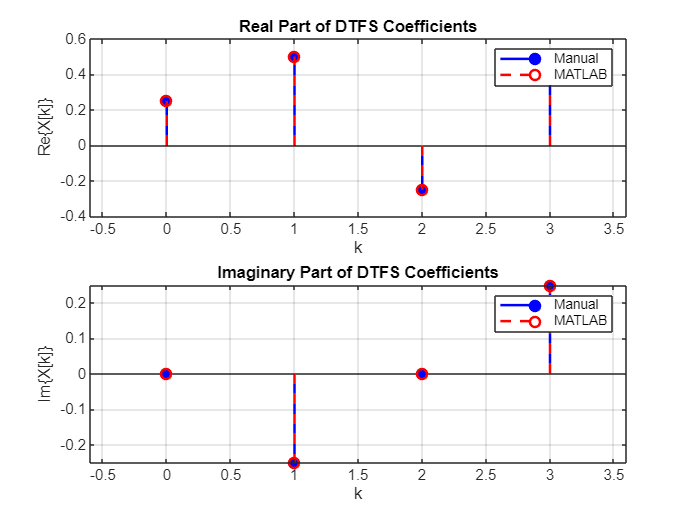

% Define the signal x[n]
x = [1 1 -1 0];    % Original signal
N = length(x);
n = 0:N-1;          % Time indices
k = 0:N-1;          % Frequency indices

% Manually computed DTFS coefficients (corrected)
X_manual = [0.25, 0.5 - 0.25j, -0.25, 0.5 + 0.25j];

% MATLAB-computed coefficients using ss_dtfs
X_matlab = ss_dtfs(x, k);

% Plot the comparison of DTFS coefficients (real and imaginary parts)
figure;

% Plot the real parts of the coefficients
subplot(2,1,1);
stem(k, real(X_manual), 'b', 'filled', 'LineWidth', 1.5); hold on;
stem(k, real(X_matlab), 'r--o', 'LineWidth', 1.5);
title('Real Part of DTFS Coefficients');
xlabel('k'); ylabel('Re\{X[k]\}');
legend('Manual', 'MATLAB');
grid on;

% Plot the imaginary parts of the coefficients
subplot(2,1,2);
stem(k, imag(X_manual), 'b', 'filled', 'LineWidth', 1.5); hold on;
stem(k, imag(X_matlab), 'r--o', 'LineWidth', 1.5);
title('Imaginary Part of DTFS Coefficients');
xlabel('k'); ylabel('Im\{X[k]\}');
legend('Manual', 'MATLAB');
grid on;

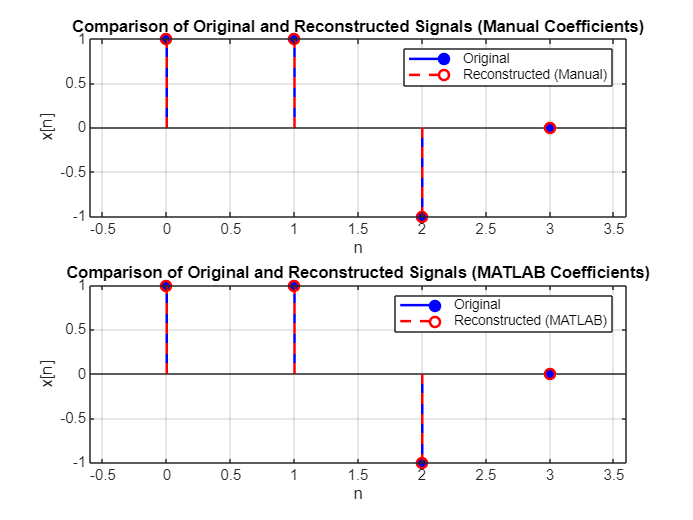


% Reconstruct signal using the manual coefficients
x_reconstructed_manual = ss_invdtfs(X_manual, n);

% Reconstruct signal using the MATLAB-calculated coefficients
x_reconstructed_matlab = ss_invdtfs(X_matlab, n);

% Plot comparison of original and reconstructed signals
figure;

% Plot the original and reconstructed signals (Manual coefficients)
subplot(2,1,1);
stem(n, x, 'b', 'filled', 'LineWidth', 1.5); hold on;
stem(n, real(x_reconstructed_manual), 'r--o', 'LineWidth', 1.5);
title('Comparison of Original and Reconstructed Signals (Manual Coefficients)');
xlabel('n'); ylabel('x[n]');
legend('Original', 'Reconstructed (Manual)');
grid on;

% Plot the original and reconstructed signals (MATLAB coefficients)
subplot(2,1,2);
stem(n, x, 'b', 'filled', 'LineWidth', 1.5); hold on;
stem(n, real(x_reconstructed_matlab), 'r--o', 'LineWidth', 1.5);
title('Comparison of Original and Reconstructed Signals (MATLAB Coefficients)');
xlabel('n'); ylabel('x[n]');
legend('Original', 'Reconstructed (MATLAB)');
grid on;


% Define the ss_dtfs function
function c = ss_dtfs(x, idx)
    c = zeros(size(idx));
    N = length(x);
    for kk = 1:length(idx)
        k = idx(kk);
        tmp = 0;
        for nn = 1:N
            n = nn - 1;
            tmp = tmp + x(nn) * exp(-1i * 2 * pi / N * k * n);
        end
        c(kk) = tmp / N;
    end
end

% Define the ss_invdtfs function
function x = ss_invdtfs(c, idx)
    x = zeros(size(idx));
    N = length(c);
    for nn = 1:length(idx)
        n = idx(nn);
        tmp = 0;
        for kk = 1:N
            k = kk - 1;
            tmp = tmp + c(kk) * exp(1i * 2 * pi / N * k * n);
        end
        x(nn) = tmp;
    end
end

Question 2(c):

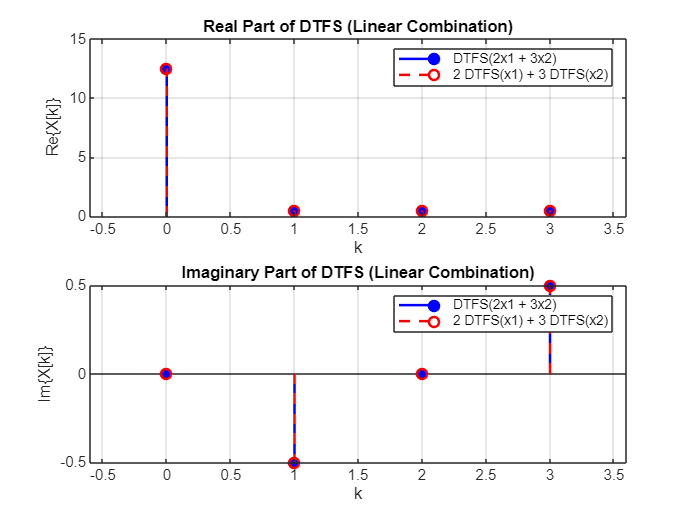

% Define the signals
x1 = [1, 2, 3, 4];
x2 = [4, 3, 2, 1];
N = length(x1);
k = 0:N-1;          % indices

% (a) Verify Linearity
% Compute DTFS of individual signals using ss_dtfs
X1_dtfs = ss_dtfs(x1, k);
X2_dtfs = ss_dtfs(x2, k);

% Compute DTFS of the linear combination
x_linear_combination = 2*x1 + 3*x2;
X_linear_combination_dtfs = ss_dtfs(x_linear_combination, k);

% Compute the linear combination of the individual DTFS
linear_combination_of_dtfs = 2*X1_dtfs + 3*X2_dtfs;

% Plot comparison for Linearity
figure;

% Plot real parts
subplot(2,1,1);
stem(k, real(X_linear_combination_dtfs), 'b', 'filled', 'LineWidth', 1.5); hold on;
stem(k, real(linear_combination_of_dtfs), 'r--o', 'LineWidth', 1.5);
title('Real Part of DTFS (Linear Combination)');
xlabel('k'); ylabel('Re\{X[k]\}');
legend('DTFS(2x1 + 3x2)', '2 DTFS(x1) + 3 DTFS(x2)');
grid on;

% Plot imaginary parts
subplot(2,1,2);
stem(k, imag(X_linear_combination_dtfs), 'b', 'filled', 'LineWidth', 1.5); hold on;
stem(k, imag(linear_combination_of_dtfs), 'r--o', 'LineWidth', 1.5);
title('Imaginary Part of DTFS (Linear Combination)');
xlabel('k'); ylabel('Im\{X[k]\}');
legend('DTFS(2x1 + 3x2)', '2 DTFS(x1) + 3 DTFS(x2)');
grid on;

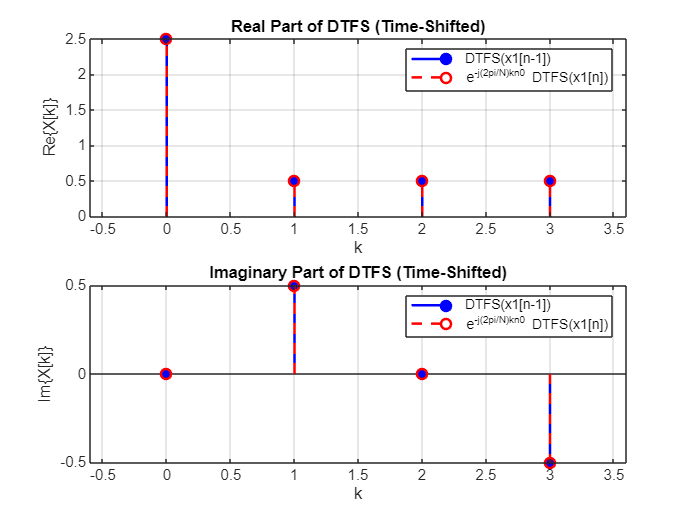



% (b) Time-Shifting Property
n0 = 1;
x1_shifted = circshift(x1, n0);

% Compute DTFS of the shifted signal
X1_shifted_dtfs = ss_dtfs(x1_shifted, k);

% Compute the DTFS of the original signal multiplied by the phase factor
phase_factor = exp(-1j*(2*pi/N)*k*n0);
time_shifted_X1_dtfs = phase_factor .* X1_dtfs;

% Plot comparison for Time-Shifting
figure;

% Plot real parts
subplot(2,1,1);
stem(k, real(X1_shifted_dtfs), 'b', 'filled', 'LineWidth', 1.5); hold on;
stem(k, real(time_shifted_X1_dtfs), 'r--o', 'LineWidth', 1.5);
title('Real Part of DTFS (Time-Shifted)');
xlabel('k'); ylabel('Re\{X[k]\}');
legend('DTFS(x1[n-1])', 'e^{-j(2pi/N)kn0} DTFS(x1[n])');
grid on;

% Plot imaginary parts
subplot(2,1,2);
stem(k, imag(X1_shifted_dtfs), 'b', 'filled', 'LineWidth', 1.5); hold on;
stem(k, imag(time_shifted_X1_dtfs), 'r--o', 'LineWidth', 1.5);
title('Imaginary Part of DTFS (Time-Shifted)');
xlabel('k'); ylabel('Im\{X[k]\}');
legend('DTFS(x1[n-1])', 'e^{-j(2pi/N)kn0} DTFS(x1[n])');
grid on;

### Question 3(b):

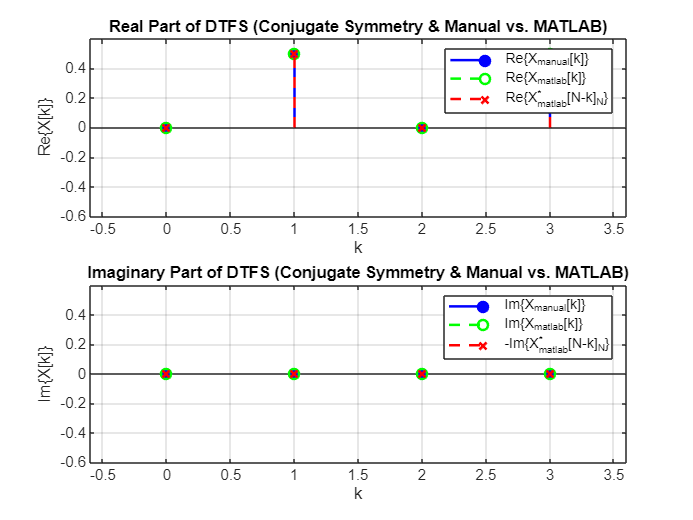

% Define the signal x[n]
x = [1, 0, -1, 0];
N = length(x);
n = 0:N-1;          % Time indices
k = 0:N-1;          % Frequency indices

% (a) Verify Conjugate Symmetry
% Compute DTFS using ss_dtfs
X_dtfs_matlab = ss_dtfs(x, k);

% Manually calculated DTFS coefficients
X_dtfs_manual = [0, 0.5, 0, 0.5];

% Compute the conjugate of X[k]
X_conjugate_matlab = conj(X_dtfs_matlab);

tolerance = 1e-10; % Define a small tolerance

% Plot comparison for Conjugate Symmetry and Manual vs. MATLAB
figure;

% Plot real parts
subplot(2,1,1);
stem(k, real(X_dtfs_manual), 'b', 'filled', 'LineWidth', 1.5); hold on;
stem(k, real(X_dtfs_matlab), 'g--o', 'LineWidth', 1.5);
stem(k, real(X_conjugate_matlab(mod(N-k, N)+1)), 'r--x', 'LineWidth', 1.5); % Using N-k
title('Real Part of DTFS (Conjugate Symmetry & Manual vs. MATLAB)');
xlabel('k'); ylabel('Re\{X[k]\}');
legend('Re\{X_{manual}[k]\}', 'Re\{X_{matlab}[k]\}', 'Re\{X^*_{matlab}[N-k]_N\}');
grid on;
ylim([-0.6 0.6]); % Set y-axis limits for better comparison

% Plot imaginary parts
subplot(2,1,2);
stem(k, imag(X_dtfs_manual), 'b', 'filled', 'LineWidth', 1.5); hold on;
stem(k, imag(X_dtfs_matlab), 'g--o', 'LineWidth', 1.5);
stem(k, -imag(X_conjugate_matlab(mod(N-k, N)+1)), 'r--x', 'LineWidth', 1.5); % -imag for conjugate
title('Imaginary Part of DTFS (Conjugate Symmetry & Manual vs. MATLAB)');
xlabel('k'); ylabel('Im\{X[k]\}');
legend('Im\{X_{manual}[k]\}', 'Im\{X_{matlab}[k]\}', '-Im\{X^*_{matlab}[N-k]_N\}');
grid on;
ylim([-0.6 0.6]); % Set y-axis limits for better comparison


% Check if manual and matlab are close
manual_matlab_diff = abs(X_dtfs_manual - X_dtfs_matlab);
disp('Difference between manual and MATLAB DTFS:');

Difference between manual and MATLAB DTFS:


disp(max(manual_matlab_diff));

   9.1849e-17



if max(manual_matlab_diff) < tolerance
    disp('Manual and MATLAB DTFS are close (within tolerance).');
else
    disp('Manual and MATLAB DTFS differ significantly.');
end

Manual and MATLAB DTFS are close (within tolerance).


### **Quesion 4(b):**

% Define signals over one period
 x = [1 2 3 4];
 h = [1 0 1 0];
 N = length(x); % Period N = 4
k = 0:N-1;
 % --- Direct Periodic Convolution using ss_pconv ---
 % ss_pconv computes the periodic convolution directly in the time domain
 y_direct = ss_pconv(x, h);
 disp('Periodic convolution y[n] using ss_pconv:');

Periodic convolution y[n] using ss_pconv:


 disp(y_direct);

     4     6     4     6




 % --- Periodic Convolution using DTFS property ---
 % Compute DTFS of x and h
 % ss_dtfs(signal) computes the entire vector of DTFS coefficients
 X = ss_dtfs(x,k);
 H = ss_dtfs(h,k);

 % Multiply DTFS coefficients (with N scaling factor)
 % Y[k] = N * X[k] * H[k] according to the chosen DTFS definition
 Y = N * X .* H;

 % Compute the inverse DTFS of Y[k] to get y[n]
 % ss_invdtfs(coefficients) computes the signal from its DTFS coefficients
 y_dtfs = ss_invdtfs(Y,k);
 disp('Periodic convolution y[n] using DTFS property:');

Periodic convolution y[n] using DTFS property:


 disp(y_dtfs);

   4.0000 - 0.0000i   6.0000 + 0.0000i   4.0000 - 0.0000i   6.0000 + 0.0000i




 % Compare the two results
 disp('Comparison of y_direct and y_dtfs (using tolerance):');

Comparison of y_direct and y_dtfs (using tolerance):


 disp(abs(y_direct - y_dtfs) < 1e-10); % Compare floating point results with tolerance

   1   1   1   1



function y = ss_pconv (x , h)
    N = length (x ); % Period for all three s i g n a l s.
    y = zeros ( size (x )); % Create all - zero vector .
    for n = 0:N -1 
        tmp = 0;
        for k = 0:N -1 
            tmp = tmp + ss_per (x ,k )* ss_per (h ,n - k );
        end 
    nn = n +1;
    y( nn ) = tmp ;
    end 
end

function xtilde = ss_per (x , idx )
    N = length (x ); % Period of the signal .
    n = mod ( idx ,N ); % Modulo i n d e x i n g .
    nn = n +1; % MATLAB i n d i c e s start with 1.
    xtilde = x ( nn );
end

### **Question 5(c):**

% Define signals over one period
 x = [1 2 1 2];
 h = [1 1 0 0];
 N = length(x); % Period N = 4
 n_values = 0:(N-1); % Time indices for plotting
 k_values = 0:(N-1); % Frequency indices for DTFS

 % --- Periodic Convolution using DTFS property ---
 % Compute DTFS of x and h
 % Assuming ss_dtfs works with the signal and a vector of k indices
 X = ss_dtfs(x, k_values);
 H = ss_dtfs(h, k_values);

 % Multiply DTFS coefficients (with N scaling factor)
 Y = N * X .* H;

 % Compute the inverse DTFS of Y[k] to get y[n]
 % Assuming ss_invdtfs works with the coefficients and a vector of k indices
 y_dtfs = ss_invdtfs(Y, k_values);
 disp('Periodic convolution y[n] using DTFS property:');

Periodic convolution y[n] using DTFS property:


 disp(y_dtfs);

   3.0000 + 0.0000i   3.0000 - 0.0000i   3.0000 - 0.0000i   3.0000 + 0.0000i




 % --- Direct Periodic Convolution using ss_pconv ---
 % ss_pconv computes the periodic convolution directly in the time domain
 y_direct = ss_pconv(x, h);
 disp('Periodic convolution y[n] using ss_pconv (direct computation):');

Periodic convolution y[n] using ss_pconv (direct computation):


 disp(y_direct);

     3     3     3     3




 % --- Compare the results ---
 disp('Comparison of y_dtfs and y_direct (using tolerance):');

Comparison of y_dtfs and y_direct (using tolerance):


 disp(abs(y_dtfs - y_direct) < 1e-10); % Compare floating point results with tolerance

   1   1   1   1




 % Define the manual calculation result for comparison
 y_manual = [3 3 3 3];
 disp('Comparison of y_direct with manual result (using tolerance):');

Comparison of y_direct with manual result (using tolerance):


 disp(abs(y_direct - y_manual) < 1e-10);

   1   1   1   1



 disp('Comparison of y_dtfs with manual result (using tolerance):');

Comparison of y_dtfs with manual result (using tolerance):


 disp(abs(y_dtfs - y_manual) < 1e-10);

   1   1   1   1



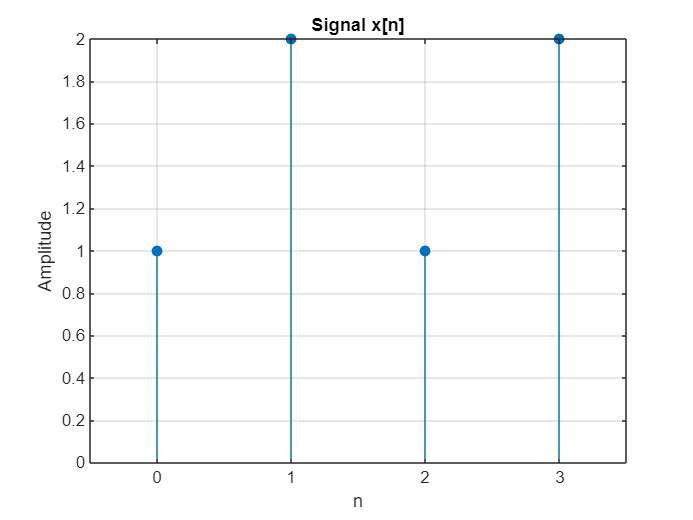



 % --- Plotting the signals ---
 % Plot x[n]
 figure;
 stem(n_values, x, 'filled');
 title('Signal x[n]');
 xlabel('n');
 ylabel('Amplitude');
 grid on;
 xlim([-0.5 N-0.5]); % Adjust x-axis limits for clarity
 xticks(n_values); % Ensure ticks are at integer sample locations

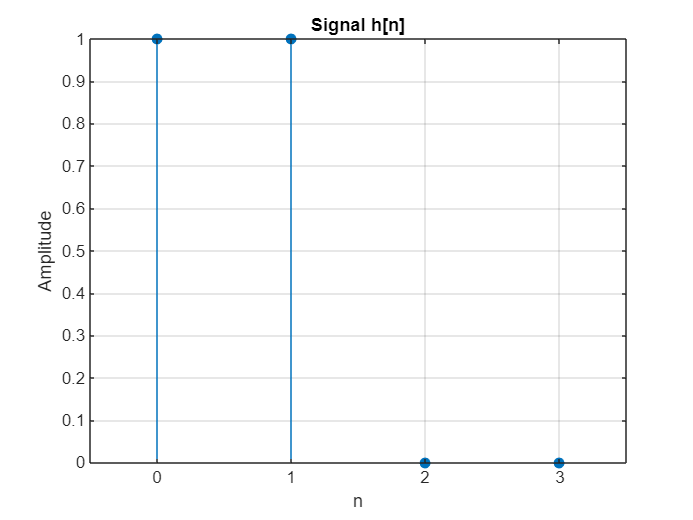



 % Plot h[n]
 figure;
 stem(n_values, h, 'filled');
 title('Signal h[n]');
 xlabel('n');
 ylabel('Amplitude');
 grid on;
 xlim([-0.5 N-0.5]); % Adjust x-axis limits for clarity
 xticks(n_values); % Ensure ticks are at integer sample locations

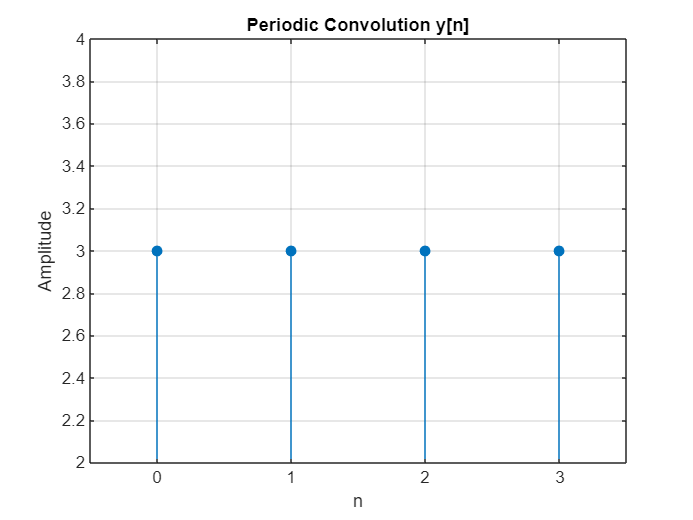



 % Plot y[n] (using the result from the DTFS method, as they should match)
 figure;
 stem(n_values, real(y_dtfs), 'filled');
 title('Periodic Convolution y[n]');
 xlabel('n');
 ylabel('Amplitude');
 grid on;
 xlim([-0.5 N-0.5]); % Adjust x-axis limits for clarity
 xticks(n_values); % Ensure ticks are at integer sample locations
 ylim([real(min(y_dtfs)-1) real(max(y_dtfs)+1)]); % Adjust y-axis limits